# Code label overlay and mask generation of images- must use TIFF files

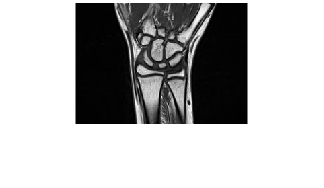

% Code for the generation of 1 mask from one image.  

imdsTr= imageDatastore(fullfile("name_file.tif"));

[I,cmap]= imread("name_file.tif",1);
figure
imshow(I,cmap)

 
classNames=["class_name"]; 
pixellabelID = [number_pixel_label_ID];
pxdsTr = pixelLabelDatastore("PixelLabelData",classNames,pixellabelID);
labels= readall(pxdsTr)

labels = 1×1 cell array
    {180×256 categorical}


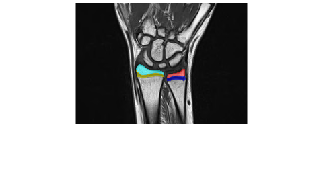


C = readimage(pxdsTr,1);
B = labeloverlay(I,C);
figure
imshow(B)


E= imread("Whitebackground.png")

E = 180×256×3 uint8 array
E(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255  


F= labeloverlay(E,C)

F = 180×256×3 uint8 array
F(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255  

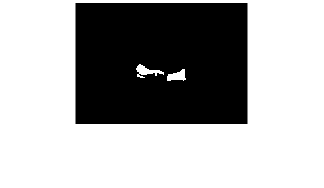

%% Image mask generation from overlay 

M1= rgb2gray(F);
M2= imbinarize(M1, 'adaptive','ForegroundPolarity','dark','Sensitivity',0.59);
M2 = imcomplement(M2);
%M2 = bwareafilt(M2,2);
%M2 = imfill(M2,"holes");
imshow(M2)

Allarea = bwarea(M2)

Allarea = 705.1250

%M3 = imcomplement(M2)
%figure
%imshow(M3)
Allarea

Allarea = 705.1250

% Count area of white area
%clear bwarea
%Allarea = bwarea(M3)